## **Fitting a Surface to Multivariable Data**

Time for the big one; you already know how to fit a polynomial to single-variable data, now its time to do it for data that has multiple inputs.

We'll start off small with fitting a plane to two variable data. Suppose you have data in the form z $=f\left(x,y\right)$, where f is made of linear functions such that:


$$Z=\;$$


You can define this system as:


$$Z=X\beta$$


Where:

$Z$ is a column vector containing observed z values

$X$ is a 3-column matrix with 1s in the 1st column (to account for $\beta_0$),  x values in the 2nd column, and y values in the 3rd

$\beta$ is a column vector containing unknown coefficients

Written out it would look like this:


$$Z\;\;\;\;\;\;\;=\;\;\;\;\;\;\;\;\;\;X\;\;\;\;\;\;\;\;\;\;\;*\;\;\;\beta$$



$$\left\lbrack \begin{array}{c}
z_1 \\
z_2 \\
z_3 \\
\ldotp \ldotp \ldotp \\
z_i 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
1 & x_1  & y_1 \\
1 & x & y_2 \\
1 & x & y_3 \\
 & \ldotp \ldotp \ldotp  & \\
1 & x_i  & y_i 
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
\beta_0 \\
\beta_1 \\
\beta_2 
\end{array}\right\rbrack$$


Note that the number of rows in the $\beta$ vector will be equal to n+1, where n is the number of input variables (x and y in this case)

If this were a perfect world, we would now be able to solve for the coefficients in $\beta$ simply by solving the system of linear equations, but alas, it is not, and we can therefore expect to find some degree of error between our calculated and measured values. We address this inconsistency by replacing our measured values $Z$ with our predicted values $\hat{Z}$ which will be the points whithin the plane-of-best-fit that are closest to the measured data.


$$\hat{Z} =X\;\hat{\beta}$$


This allows us to create a vector $e$ representing the difference between the two, this vector is often referred to as the residual or error vector


$$e=Z-\hat{Z}$$



$$e=Z-X\;\hat{\beta}$$


We want to minimize this error in order to have the best fit, and this means making sure that the path from the points in $Z$ to the plane $X$ are as direct as possible, in other words, $e$ must be normal (perpendicular) to the column space of $X$. Which by extension means that  $e$ must be perpendicular to every column in $X$, Therefore


$$X^T e=0$$


We can then substitute $e=Z-X\;\hat{\beta}$ :


$$X^T \left(Z-X\;\hat{\beta} \right)=0$$


Distribute $X^T$:


$$X^T Z-X^T X\;\hat{\beta} =0$$


And rearrange to arrive at the normal equation:


$$X^T X\;\hat{\beta} =X^T Z$$


Which can then be rearranged one last time to give us an equation for $\hat{\beta}$:


$$\hat{\beta} ={{\left(X^T X\right)}^{-1} \;X}^T Z$$


And with that, we are able to solve for $\hat{\beta}$!  Let's give it a try with some data.

Consider the x, y, z points (1,1,4), (1, 2, 4), (2, 1, 5), and (2, 2, 5).

**Step 1: **Set up your matrices


$$X=\left\lbrack \begin{array}{ccc}
1 & 1 & 1\\
1 & 1 & 2\\
1 & 2 & 1\\
1 & 2 & 2
\end{array}\right\rbrack \;\;\;\;\;\;\;\;Z=\left\lbrack \begin{array}{c}
4\\
4\\
5\\
5
\end{array}\right\rbrack \;$$


**Step 2: **Calculate $X^T X$

$X^T X$ = $\left\lbrack \begin{array}{cccc}
1 & 1 & 1 & 1\\
1 & 1 & 2 & 2\\
1 & 2 & 1 & 2
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
1 & 1 & 1\\
1 & 1 & 2\\
1 & 2 & 1\\
1 & 2 & 2
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
4 & 6 & 6\\
6 & 10 & 9\\
6 & 9 & 10
\end{array}\right\rbrack$

**Step 3: **Calculate $X^T Z$


$$X^T Z=\;$$

$$\left\lbrack \begin{array}{cccc}
1 & 1 & 1 & 1\\
1 & 1 & 2 & 2\\
1 & 2 & 1 & 2
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
4\\
4\\
5\\
5
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
18\\
28\\
27
\end{array}\right\rbrack$$


**Step 4: ** Solve for $\hat{\beta}$


$${\left\lbrack \begin{array}{ccc}
4 & 6 & 6\\
6 & 10 & 9\\
6 & 9 & 10
\end{array}\right\rbrack }^{-1} \left\lbrack \begin{array}{c}
18\\
28\\
27
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
3\\
1\\
0
\end{array}\right\rbrack$$


We now have our values for the coefficients in $\hat{\beta}$, remember that they are in order of increasing degree and correspond to the order of terms in our X matrix. Therefore, the equation for the plane of best fit is:


$$z=3+x+0$$


This takes up quite a bit of time though, MATLAB is thankfully much faster:

x = [1 1 2 2];
y = [1 2 1 2];
z = [4 4 6 5];
Data = [x;
        y;
        z]

Data =      1     1     2     2
     1     2     1     2
     4     4     6     5


X = ones(size(Data,2),1);
X = [X,Data(1:2,:)'];
Z = Data(3,:)';

PlaneCoeff = (inv(X'*X)) * X' * Z;
% MATLAB also has this operation that is more numerically stable and faster than using inv()
PlaneCoeff = X \ Z

PlaneCoeff =     3.2500
    1.5000
   -0.5000


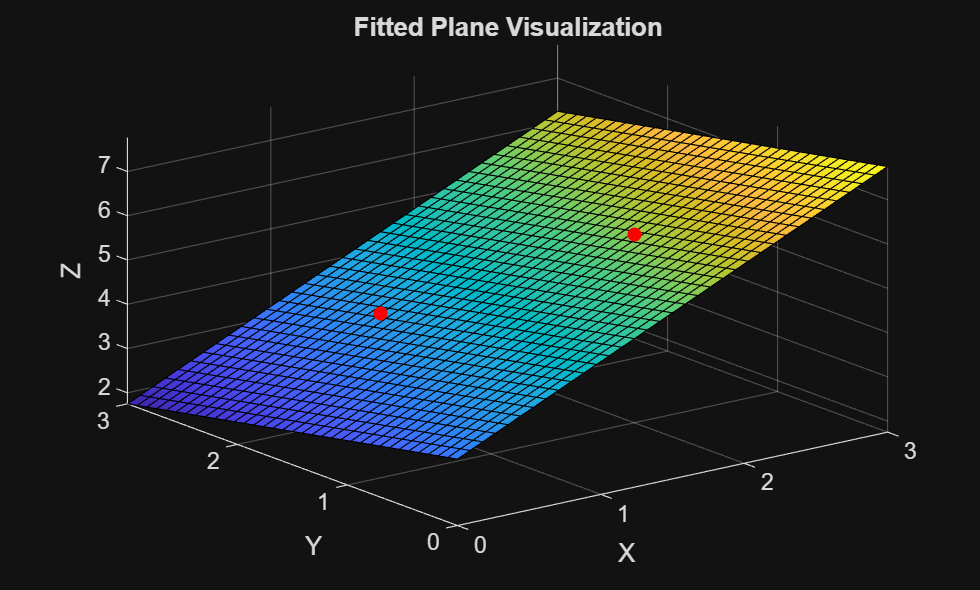

% Create the anonymous function using the solved coefficients
fittedPlane = @(x, y) PlaneCoeff(1) + PlaneCoeff(2)*x + PlaneCoeff(3)*y;

% Now visualize it using fsurf
fsurf(fittedPlane, [0 3])
hold on
scatter3(Data(1,:), Data(2,:), Data(3,:), 'filled', 'r') % Plot the original points
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Fitted Plane Visualization');
hold off

**Fitting a Quadratic Surface to Data**

Now that you're familiar with how to fit a plane to data, let's expand a bit and move to fitting quadratic surfaces instead of planes. This will give us significantly more accuracy especially for more complex data sets. Thankfully for us, it's not that much harder than fitting a plane to a data set is, the math stays the same, we just need more terms in $\beta$ and have to deal with way bigger matrices.

The number of terms we need in $\beta$ for a bivariate polynomial is given by the equation:


$$k=\frac{\left(n+1\right)\left(n+2\right)}{2}$$


Where:

k is the total number of terms in $\beta$ and the resulting surface equation

and n is the degree of the surface we are fitting to the data (2 in this case)

Since we are fitting a quadratic surface, the number of terms we'll need in our $\beta$ vector is 6, and our function should take the form: 


$$Z=\beta_0 +\beta_1 \;x+\beta_2 \;y+\beta_3 {\;x}^2 +\beta_4 {\;y}^2 +\beta_5 \;x\;y$$


Where:

$\beta_0$ is the z-intercept

$\beta_1 \;\mathrm{and}\;\beta_2$ control linear tilt (slope)

$\beta_3 \;\mathrm{and}\;\beta_4$ control the parabola's curve along the x and y axes (concavity)

$\beta_5$ twists the surface to make saddles

We can express this system as the following equation


$$Z\;\;\;\;\;\;\;=\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;X\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;*\;\;\beta$$



$$\left\lbrack \begin{array}{c}
z_1 \\
z_2 \\
z_3 \\
\ldotp \ldotp \ldotp \\
z_i 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccccc}
1 & x_1  & y_1  & x_1^2  & y_1^2  & x_1 y_1 \\
1 & x_2  & y_2  & x_2^2  & y_2^2  & x_2 y_2 \\
1 & x_3  & y_3  & x_3^2  & y_3^2  & x_3 y_3 \\
 &  & \ldotp \ldotp \ldotp  &  & \ldotp \ldotp \ldotp  & \\
1 & x_i  & y_i  & x_i^2  & y_i^2  & x_i y_i 
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
\beta_0 \\
\beta_1 \\
\beta_2 \\
\beta_3 \\
\beta_4 \\
\beta_5 
\end{array}\right\rbrack$$


The way to solve for $\beta$ remains the same


$$\hat{\beta} ={{\left(X^T X\right)}^{-1} \;X}^T Z$$


Give it a try with this data set down below, feel free to reference earlier work if necessary. 

% Define the data points
x = [0 1.5 0 -1 0 1];
y = [0 0 1 2 -1 1];
z = [0 4 1 5 1 3];
% Consider reformating/restructuring the data to make it easier to
% manipulate

% Build the X and Z matrix

% YOUR CODE HERE

% Solve for the 6 coefficients

% YOUR CODE HERE

% Create an anonymous function using the solved coefficients
% make sure to use element-wise operators (.^ and .*) for fsurf compatibility

% YOUR CODE HERE

% Now visualize your function using fsurf

% YOUR CODE HERE

